## Wing Design

global airfoil cruise1 cruise2 C_cruise Wto Swet_SrefWing Swet_SrefBody l_d bdes bodyDiameter Srefdes Damping tolerance
bodyDiameter = 6.38;
Damping = 0.03;
tolerance = 1e-3;
cruise1 = AirCondition()

cruise1 =   AirCondition with properties:

      M: []
      V: []
      h: []
    rho: []
      T: []
      a: []
      P: []
     nu: []
     mu: []
     Re: []


cruise1.M = 1.1;
cruise1.h = convlength(28000, 'ft','m');

cruise2 = AirCondition()

cruise2 =   AirCondition with properties:

      M: []
      V: []
      h: []
    rho: []
      T: []
      a: []
      P: []
     nu: []
     mu: []
     Re: []


cruise2.V = convvel(400, 'kts', 'm/s');
cruise2.h = convlength(18000, 'ft','m');
cruise2 = cruise2.calcM();

C_cruise = 0.5 ./ 3600;
Wto = 4.2188*1e5*9.81;
Swet_SrefWing = 2.2;
Swet_SrefBody = 5;
l_d = 10;

## 1.Design CL

CLdesC1 = 0.4623;
CLdesC2 = 0.3008;

## 2.Airfoil Selection

1.Choose a t/c ratio optimum for the cruise speed

2.Choose a CLopt (at L/D max or called drag-bucket) close to design CL

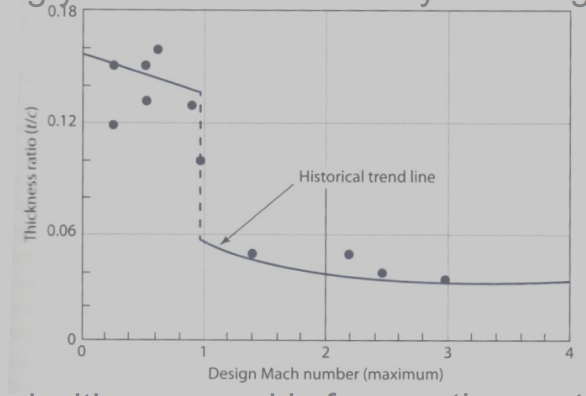

kA= 0.93;
Lambdades = 30*pi/180;
MDD = 0.9;
t_cdes = cos(Lambdades)*(kA - MDD*cos(Lambdades) - CLdesC1/(10*cos(Lambdades)^2) )

Unrecognized function or variable 'CLdesC1'.

### Conclusion:

polarName = "xf-sc21010-il-1000000.csv";
shapeName = "sc21010.dat.txt";
airfoil = Airfoil();
airfoil = airfoil.readPolar(polarName);
airfoil = airfoil.readShape(shapeName);
airfoil = airfoil.interpShape(9);

## 3.Shape

1.Use MDO to get best geometry

    -Make sure it is applicable to double-tapered, swept wing

    -At each iteration inside MDO, calculate the optimum twist to give elliptical lift distribution

    -Use a validated wing weight estimation model

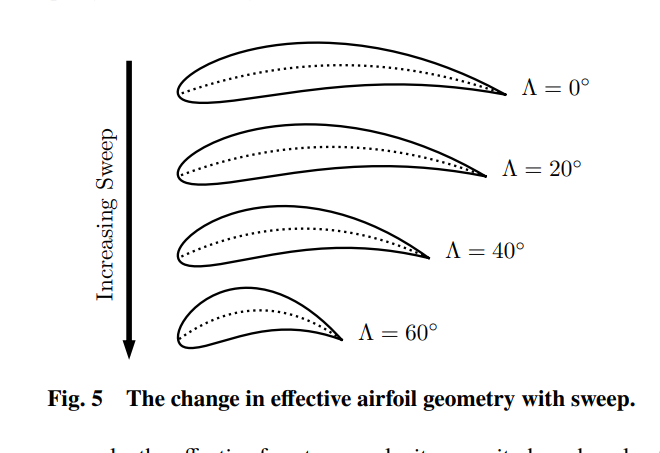

    "error = "    "34.3889"

    "error = "    "32.7521"

    "error = "    "31.3547"

    "error = "    "30.0347"

    "error = "    "28.796"

    "error = "    "27.6195"

    "error = "    "26.5012"

    "error = "    "25.435"

    "error = "    "24.4171"

    "error = "    "23.4442"

    "error = "    "22.5135"

    "error = "    "21.6223"

    "error = "    "20.7686"

    "error = "    "19.9504"

    "error = "    "19.1658"

    "error = "    "18.4131"

    "error = "    "17.6909"

    "error = "    "16.9977"

    "error = "    "16.3321"

    "error = "    "15.6931"

    "error = "    "15.0793"

    "error = "    "14.4897"

    "error = "    "13.9233"

    "error = "    "13.3792"

    "error = "    "12.8563"

    "error = "    "12.3538"

    "error = "    "11.8708"

    "error = "    "11.4067"

    "error = "    "10.9605"

    "error = "    "10.5317"

    "error = "    "10.1196"

    "error = "    "9.7233"

    "error = "    "9.3425"

    "error = "    "8.9763"

    "error = "    "

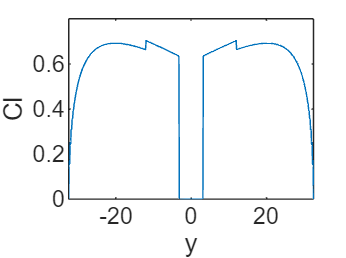

CL = 0.5600

CD = 0.0144

CLy =   -32.5000  -32.3700  -32.2400  -32.1100  -31.9800  -31.8500  -31.7200  -31.5900  -31.4600  -31.3300  -31.2000  -31.0700  -30.9400  -30.8100  -30.6800  -30.5500  -30.4200  -30.2900  -30.1600  -30.0300  -29.9000  -29.7700  -29.6400  -29.5100  -29.3800  -29.2500  -29.1200  -28.9900  -28.8600  -28.7300  -28.6000  -28.4700  -28.3400  -28.2100  -28.0800  -27.9500  -27.8200  -27.6900  -27.5600  -27.4300  -27.3000  -27.1700  -27.0400  -26.9100  -26.7800  -26.6500  -26.5200  -26.3900  -26.2600  -26.1300
         0    0.1697    0.1556    0.2528    0.2451    0.3091    0.3089    0.3534    0.3579    0.3902    0.3973    0.4217    0.4301    0.4490    0.4578    0.4730    0.4817    0.4943    0.5026    0.5132    0.5210    0.5301    0.5374    0.5453    0.5520    0.5591    0.5652    0.5715    0.5771    0.5828    0.5879    0.5930    0.5977    0.6023    0.6066    0.6108    0.6148    0.6186    0.6222    0.6257    0.6290    0.6322    0.6353    0.6382    0.6410    0.6437    0.6462    0.6487    0.6510   


% Initial guess
% wing span fixed to 65
bdes = 65;
x0 = [10, 8, 5, 31*pi/180, 25*pi/180, 12, deg2rad(1.3)];
%x0 = [cr, ck, ct, Lambdain50, Lambdaout50, yk, maxtwist in radians]
% Design variables 
lb = x0.*0.5;
%lb(7) = deg2rad(3);
ub = x0.*1.5;
%ub(7) = deg2rad(3);
wing0 = x2wing(x0);
cruise1 = cruise1.init(wing0.cbar);
[CL, CD, CLy] = LLESwept(wing0, airfoil, cruise1)

%wingMDO(x0)
% Optimization options
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
% Run the optimization
[x_opt, fval] = fmincon(@wingMDO, x0, [], [], [], [], lb, ub, @constraintFunction, options);

    "error = "    "34.3889"

    "error = "    "32.7521"

    "error = "    "31.3547"

    "error = "    "30.0347"

    "error = "    "28.796"

    "error = "    "27.6195"

    "error = "    "26.5012"

    "error = "    "25.435"

    "error = "    "24.4171"

    "error = "    "23.4442"

    "error = "    "22.5135"

    "error = "    "21.6223"

    "error = "    "20.7686"

    "error = "    "19.9504"

    "error = "    "19.1658"

    "error = "    "18.4131"

    "error = "    "17.6909"

    "error = "    "16.9977"

    "error = "    "16.3321"

    "error = "    "15.6931"

    "error = "    "15.0793"

    "error = "    "14.4897"

    "error = "    "13.9233"

    "error = "    "13.3792"

    "error = "    "12.8563"

    "error = "    "12.3538"

    "error = "    "11.8708"

    "error = "    "11.4067"

    "error = "    "10.9605"

    "error = "    "10.5317"

    "error = "    "10.1196"

    "error = "    "9.7233"

    "error = "    "9.3425"

    "error = "    "8.9763"

    "error = "    "

wing_opt =  x2wing(x_opt);
wing_opt = wing_opt.calcSref();
figure(1)
clf;
subplot(2,1,1)
wing0.plotWing()
title("Initial")
axis equal
subplot(2,1,2)
wing_opt.plotWing()
title("Optimzed")
yline(bodyDiameter/2)
hold on
yline(-bodyDiameter/2)
axis equal

save("wing_opt.mat","wing_opt")

Analyse the aero characteristic of opt wing:

During cruise1:

%load("wing_opt.mat")
cruise1 = cruise1.init(wing_opt.cbar)
[CL1, CDi1, Cly1] = LLESwept(wing_opt, airfoil, cruise1)
CDF1 = CDFfun(cruise1.M, cruise1.Re, wing_opt, airfoil.x_cm, airfoil.t_c, l_d, Swet_SrefWing, Swet_SrefBody);
CDW1 = CDWfun(wing_opt,Cly1,cruise1.M,airfoil.t_c);
CDtotal1 = CDF1 + CDW1 + CDi1;

disp(["L/D: ", CL1/ CDtotal1])
disp(["CLclean: ", CL1])
disp(["Sref: ", wing_opt.SREF])
disp(["Maximum twist(degrees)", wing_opt.twist_max * 180/pi])
disp(["Inner sweep angle(degrees)", wing_opt.Lambdain50 * 180/pi])
disp(["Outer sweep angle(degrees)", wing_opt.Lambdaout50 * 180/pi])
disp(wing_opt)

## 4.Dihedral

-G17 presents a quantitative estimate

## 5.HLD

1.Calculate CLmax requirement at landing and takeoff

2.Select

## 6.Control Surfaces

## 7.Tailplane design

## 8.Nose shape optimization